# Lecture 6: Spatial Filtering

# Part 1: Smoothing Filters

Author: Dr. Zeynep Cipiloglu Yildiz

Notes:

- Sample images are available in the images folder of the current directory. (You may need to add images folder into your path.)

- Related lecture: Lecture6 - Spatial Filtering

- pdf versions of the .mlx files are also available for those using GNU Octave

% clear workspace variables and close windows
clc, clearvars, close all;

% read input image
I = imread('images/Lena.tif');

## Standard averaging (box) filter

f1 = fspecial('average')

f1 =     0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111
    0.1111    0.1111    0.1111


f2 = fspecial('average',7)

f2 =     0.0204    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204
    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204
    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204
    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204
    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204
    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204
    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204    0.0204


f3 = fspecial('average',15)

f3 =     0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044
    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044
    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044
    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044
    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044
    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044
    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.0044    0.004

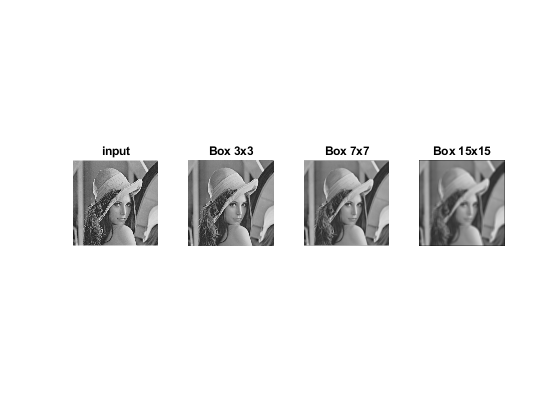

I1 = imfilter(I,f1);
I2 = imfilter(I,f2);
I3 = imfilter(I,f3);

figure, subplot(1,4,1), imshow(I), title('input');
subplot(1,4,2), imshow(I1), title('Box 3x3');
subplot(1,4,3), imshow(I2), title('Box 7x7');
subplot(1,4,4), imshow(I3), title('Box 15x15');

## Box vs. Gaussian filter

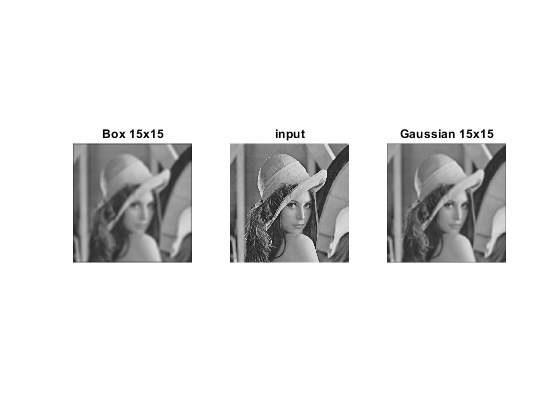

f1 = fspecial('average',15);
f2 = fspecial('gaussian',15,3);

I4 = imfilter(I,f1);
I5 = imfilter(I,f2);

figure, subplot(1,3,1), imshow(I4), title('Box 15x15') ;
subplot(1,3,2), imshow(I), title('input');
subplot(1,3,3), imshow(I5), title('Gaussian 15x15');

## Gaussian filters with different standard deviations

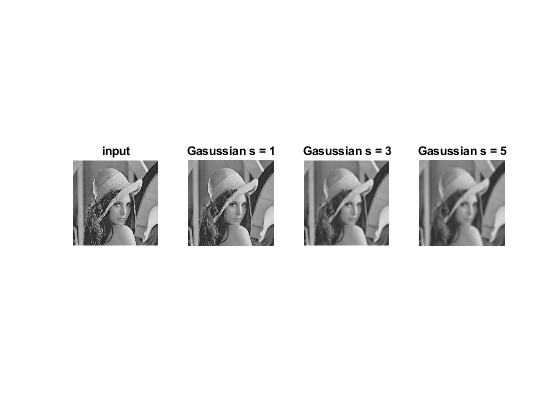

I6 = imgaussfilt(I,1);
I7 = imgaussfilt(I,3);
I8 = imgaussfilt(I,5);

figure, subplot(1,4,1), imshow(I), title('input');
subplot(1,4,2), imshow(I6), title('Gasussian s = 1');
subplot(1,4,3), imshow(I7), title('Gasussian s = 3');
subplot(1,4,4), imshow(I8), title('Gasussian s = 5');

## Specifying custom filters

mask = [0 0 1 0 0; 0 0 3 0 0; 1 3 5 3 1; 0 0 3 0 0; 0 0 1 0 0];
mask = mask/sum(mask(:))

mask =          0         0    0.0476         0         0
         0         0    0.1429         0         0
    0.0476    0.1429    0.2381    0.1429    0.0476
         0         0    0.1429         0         0
         0         0    0.0476         0         0


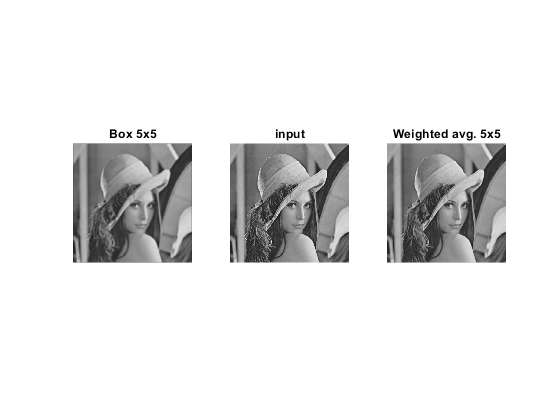

out = imfilter(I,mask);

figure, subplot(1,3,1), imshow(I2), title('Box 5x5') ;
subplot(1,3,2), imshow(I), title('input');
subplot(1,3,3), imshow(out), title('Weighted avg. 5x5');